# WBE performance by campus

Analysis of RT-PCR quantified SARS-CoV-2 viral loads in wastewater samples across 38 college campuses across Mexico

## Importing clinical reports

opts = delimitedTextImportOptions("NumVariables", 35, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Ano", "Semana", "Dia", "AGUASCALIENTES", "BAJACALIFORNIA", "BAJACALIFORNIASUR", "CAMPECHE", "CHIAPAS", "CHIHUAHUA", "DISTRITOFEDERAL", "COAHUILA", "COLIMA", "DURANGO", "GUANAJUATO", "GUERRERO", "HIDALGO", "JALISCO", "MEXICO", "MICHOACAN", "MORELOS", "NAYARIT", "NUEVOLEON", "OAXACA", "PUEBLA", "QUERETARO", "QUINTANAROO", "SANLUISPOTOSI", "SINALOA", "SONORA", "TABASCO", "TAMAULIPAS", "TLAXCALA", "VERACRUZ", "YUCATAN", "ZACATECAS"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
ConcentradoCasosDiarios = readtable("/MATLAB Drive/Analisis de datos MARTEC/Concentrado casos diarios.csv", opts)

ConcentradoCasosDiarios = 541x35 table
    Ano     Semana    Dia    AGUASCALIENTES    BAJACALIFORNIA    BAJACALIFORNIASUR    CAMPECHE    CHIAPAS    CHIHUAHUA    DISTRITOFEDERAL    COAHUILA    COLIMA    DURANGO    GUANAJUATO    GUERRERO    HIDALGO    JALISCO    MEXICO    MICHOACAN    MORELOS    NAYARIT    NUEVOLEON    OAXACA    PUEBLA    QUERETARO    QUINTANAROO    SANLUISPOTOSI    SINALOA    SONORA    TABASCO    TAMAULIPAS    TLAXCALA    VERACR

clear opts

## Importing MARTEC registries


opts = delimitedTextImportOptions("NumVariables", 7, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Semana", "Campus", "Ncampus", "Edificio", "Sitio", "Estado", "Copias_L"];
opts.VariableTypes = ["double", "categorical", "double", "double", "categorical", "categorical", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Campus", "Sitio", "Estado"], "EmptyFieldRule", "auto");

% Import the data
MARTEC_Datos= readtable("/MATLAB Drive/Analisis de datos MARTEC/MARTEC_Datos.csv", opts)

MARTEC_Datos = 9690x7 table
    Semana        Campus        Ncampus    Edificio          Sitio               Estado         Copias_L 
    ______    ______________    _______    ________    __________________    ______________    __________

       5      Aguascalientes       1          6        LIFE                  AGUASCALIENTES             0
       7      Aguascalientes       1          6        LIFE                  AGUASCALIENTES    1.3408e+05
       8      Aguascalientes       1          1        Colector principal    AGUASCALIENTES    1.4648e+06
       9      Aguascalientes       1          6        LIFE                  AGUASCALIENTES             0
      10      Aguascalientes       1          5        CEDIAM                AGUASCALIENTES      

clear opts

MARTEC_Datos(MARTEC_Datos.Ncampus==0,:)=[] %Clears registries not associated to any specific campus

MARTEC_Datos = 9664x7 table
    Semana        Campus        Ncampus    Edificio          Sitio               Estado         Copias_L 
    ______    ______________    _______    ________    __________________    ______________    __________

       5      Aguascalientes       1          6        LIFE                  AGUASCALIENTES             0
       7      Aguascalientes       1          6        LIFE                  AGUASCALIENTES    1.3408e+05
       8      Aguascalientes       1          1        Colector principal    AGUASCALIENTES    1.4648e+06
       9      Aguascalientes       1          6        LIFE                  AGUASCALIENTES             0
      10      Aguascalientes       1          5        CEDIAM                AGUASCALIENTES      

load("Heatmap_MARTEC.mat") %Loads the color map for the resulting heatmap

## **Calculates the weekly average of new daily cases for each state**

ConcentradoCasosDiarios(:,["Ano","Dia"])=[];
VarEst=ConcentradoCasosDiarios.Properties.VariableNames;
Estados=ConcentradoCasosDiarios.Properties.VariableNames(2:end);
Semanas=[1:1:78]';
Casos=zeros(78,32);

for i=1:1:78
    DatoSem=table2array(ConcentradoCasosDiarios(ConcentradoCasosDiarios.Semana==i,2:end));
    PromSem=mean(DatoSem,1);
    Casos(i,:)=PromSem;
end

Casos=[Semanas Casos];
CasosDiarios=array2table(Casos,"VariableNames",VarEst);

## Summarizes sampling for each campus

Campuses=max(MARTEC_Datos.Ncampus);
ResumenCampus=[];
for i=1:1:Campuses
    DatoCampus=MARTEC_Datos(MARTEC_Datos.Ncampus==i,:);
    Muestras=size(DatoCampus,1);
    SemMuestreo=size(unique(DatoCampus.Semana),1);
    EdMuestreo=size(unique(DatoCampus.Edificio),1);
    NumCampus=i;
    ResumenCampus(i,:)=[NumCampus Muestras SemMuestreo EdMuestreo];
end
ResumenCampus=[ResumenCampus];
ResumenCampus=array2table(ResumenCampus,"VariableNames",["Campus" "Total samples" "Weekly samplings" "Buildings"])

ResumenCampus = 39x4 table
    Campus    Total samples    Weekly samplings    Buildings
    ______    _____________    ________________    _________

       1           258                61               9    
       2           377                60              14    
       3           281                60               8    
       4            58                58               4    
       5            98                59               4    
       6           502                60              14    
       7            58                54               4    
       8            57                53               5    
       9           133                52               4    
      10            36                36               1    
      11            56                53               4    
      12           373                55   

## Evaluates correlation between viral loads in wastewater samples clustered by campus and clinical COVID-19 incident reports

EvalPearson=[];
Pearsons=[];
Cluster_Campus=[];
for j=1:1:Campuses
DatoCampus=sortrows(MARTEC_Datos(MARTEC_Datos.Ncampus==j,:),"Semana","ascend");
TotEd=double(table2array(ResumenCampus(ResumenCampus.Campus==j,"Buildings")));
semanas=unique(DatoCampus.Semana);
InfoCampus=[];
for i=1:1:78
    DatoSemCampus=DatoCampus(DatoCampus.Semana==i,:);
    if size(DatoSemCampus,1)>0
        Muestras=size(DatoSemCampus,1);
        XMuestreo=Muestras/TotEd;
        PromCopias=mean(DatoSemCampus.Copias_L,1);
        MaxCopias=max(DatoSemCampus.Copias_L);
        MPositivas=sum(DatoSemCampus.Copias_L>0);
        XMuestrasPos=MPositivas/Muestras;
        XEdPositivos=MPositivas/TotEd;
        InfoCampus(i,:)=[j i Muestras XMuestreo PromCopias MaxCopias MPositivas XMuestrasPos XEdPositivos];
    else
        Muestras=0;
        XMuestreo=0;
        PromCopias=0;
        MaxCopias=0;
        MPositivas=0;
        XMuestrasPos=0;
        XEdPositivos=0;
        InfoCampus(i,:)=[j i Muestras XMuestreo PromCopias MaxCopias MPositivas XMuestrasPos XEdPositivos];
    end 
end
CasosEstado=table2array(CasosDiarios(:,strrep(string(DatoCampus.Estado(1,1))," ","")));
InfoCampus=array2table([InfoCampus CasosEstado],"VariableNames",["NCampus","Semana","Muestras totales","% Muestreo", "Promedio de copias", "Máximo de copias", "Muestras positivas", "% Muestras positivas", "% Ed. Positivos", "Casos diarios"]);
InfoCampus(InfoCampus.("Muestras totales")==0,:)=[]; %Eliminates empty data points
[CPro,PvPro]=corrcoef(InfoCampus.("Promedio de copias"),InfoCampus.("Casos diarios")); %Correlation per average number of viral copies
CPro=CPro(2,1);
PvPro=PvPro(2,1);
[CMax,PvMax]=corrcoef(InfoCampus.("Máximo de copias"),InfoCampus.("Casos diarios")); %Correlation per maximum number of viral copies
CMax=CMax(2,1);
PvMax=PvMax(2,1);
[CMue,PvMue]=corrcoef(InfoCampus.("% Muestras positivas"),InfoCampus.("Casos diarios")); %Correlation per rate of positive samples
CMue=CMue(2,1);
PvMue=PvMue(2,1);
[CEd,PvEd]=corrcoef(InfoCampus.("% Ed. Positivos"),InfoCampus.("Casos diarios")); %Correlation per rate of positive buildings
CEd=CEd(2,1);
PvEd=PvEd(2,1);
Cobertura=mean(InfoCampus.("% Muestreo"),1);
DEstCobertura=std(InfoCampus.("% Muestreo"),1);
SemConsideradas=size(InfoCampus,1);
Pearsons=[j TotEd SemConsideradas Cobertura DEstCobertura CPro PvPro CMax PvMax CMue PvMue CEd PvEd];
EvalPearson(j,:)=Pearsons;
Pearsons=[];
Cluster_Campus=[Cluster_Campus;InfoCampus];
end
Cols=["Campus", "Buildings","Weeks","Avg. Coverage","St. Dev. Coverage", "Corr_mean","p1","Corr_max","p2","Corr_PositiveSamples","p3","Corr_PositiveBuildings","p4"];
EvalPearson=array2table(EvalPearson,"VariableNames",Cols);

## Creates a matrix of locations were SARS-CoV-2 was successfully detected

HResumen=[];
for i=1:1:Campuses
    HCampus=sortrows(MARTEC_Datos(MARTEC_Datos.Ncampus==i,:),"Semana","ascend");
    for j=1:1:78
        HSemCampus=HCampus(HCampus.Semana==j,:);
        if size(HSemCampus,1)==0
            HResumen(i,j)=-1;
        else
            if max(HSemCampus.Copias_L)==0
                HResumen(i,j)=0;
            else
                HResumen(i,j)=1;
            end
        end
    end
end
HResumen(:,1:4)=[]

HResumen =      0    -1     1     1     0     1     1     1     1    -1     0     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     1     1     1     1     0     0     1     1     1     1     1     1     0    -1    -1    -1    -1
    -1     0     0     0     0     0     0     0     0    -1     0     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     1     1     1     1     1     1     1    -1    -1    -1    -1
    -1    -1     1     1     1     1     1     0     1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     0     1     1     1     1     1     1     1     0     0     1     1     1     0     1     0     0    -1    -1    -1    -1
    -1    -1    -1     1    -1     1     0     1     0     0     0    -1     0     0  

HResumen();

## Creates the detection heatmap

[~,ia,ic]=unique(MARTEC_Datos.Campus);
Campus_Est=MARTEC_Datos(ia,["Ncampus","Campus","Estado"]);
Campus_Est=sortrows(Campus_Est,"Estado","ascend");
HResumen=HResumen(Campus_Est.Ncampus,:);
[~,ia]=unique(Campus_Est.Estado)

ia =      1
     2
     3
     5
     7
    10
    13
    14
    16
    19


HeatCampus=heatmap(HResumen,"YLabel","Campus","XLabel","Week","XDisplayLabels",[5:1:78],"YDisplayLabels",Campus_Est.Campus,"Colormap",Heatmap_MARTEC,"fontsize",8)

HeatCampus =   HeatmapChart with properties:

        XData: {74x1 cell}
        YData: {39x1 cell}
    ColorData: [39x74 double]

  Show all properties


colorbar off
title("SARS-CoV-2 detection per campus")
fig = gcf;
ax_pos = HeatCampus.Position;
numRows = size(HResumen, 1);
numCols = size(HResumen, 2);

y_cats=[];
mismo_estado=[];
for i = 1:numel(ia)-1
    y = ax_pos(2) + (1 - (ia(i) - 1) / numRows) * ax_pos(4);
    y_cats=[y_cats;y];
    if ia(i+1)-ia(i)>=2
        mismo_estado=[mismo_estado;1];
    else
        mismo_estado=[mismo_estado;0];
    end
end

y_coor=[];
for i=1:numel(mismo_estado)-1
    y_coor=[y_coor; y_cats(i) y_cats(i+1)];
end
y_coor=[y_coor;y_cats(end) ax_pos(2)]

y_coor =     0.9250    0.9041
    0.9041    0.8832
    0.8832    0.8414
    0.8414    0.7996
    0.7996    0.7369
    0.7369    0.6742
    0.6742    0.6533
    0.6533    0.6115
    0.6115    0.5488
    0.5488    0.5279


y_coor(:,1)=y_coor(:,1)-0.005

y_coor =     0.9200    0.9041
    0.8991    0.8832
    0.8782    0.8414
    0.8364    0.7996
    0.7946    0.7369
    0.7319    0.6742
    0.6692    0.6533
    0.6483    0.6115
    0.6065    0.5488
    0.5438    0.5279


y_coor(:,2)=y_coor(:,2)+0.005

y_coor =     0.9200    0.9091
    0.8991    0.8882
    0.8782    0.8464
    0.8364    0.8046
    0.7946    0.7419
    0.7319    0.6792
    0.6692    0.6583
    0.6483    0.6165
    0.6065    0.5538
    0.5438    0.5329


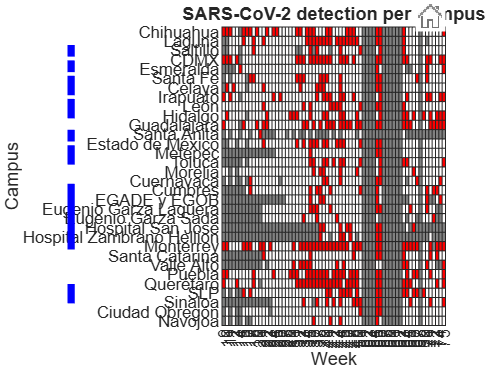


for i=1:1:height(y_coor)
    if mismo_estado(i)==0
        continue;
    else
        annotation(fig,"line",[0.1445,0.1445],y_coor(i,:),'color','b','LineWidth',3.5);
    end
end